# Demarce Williams

## 4 by 2 Rectaqngle centered at (0,0)

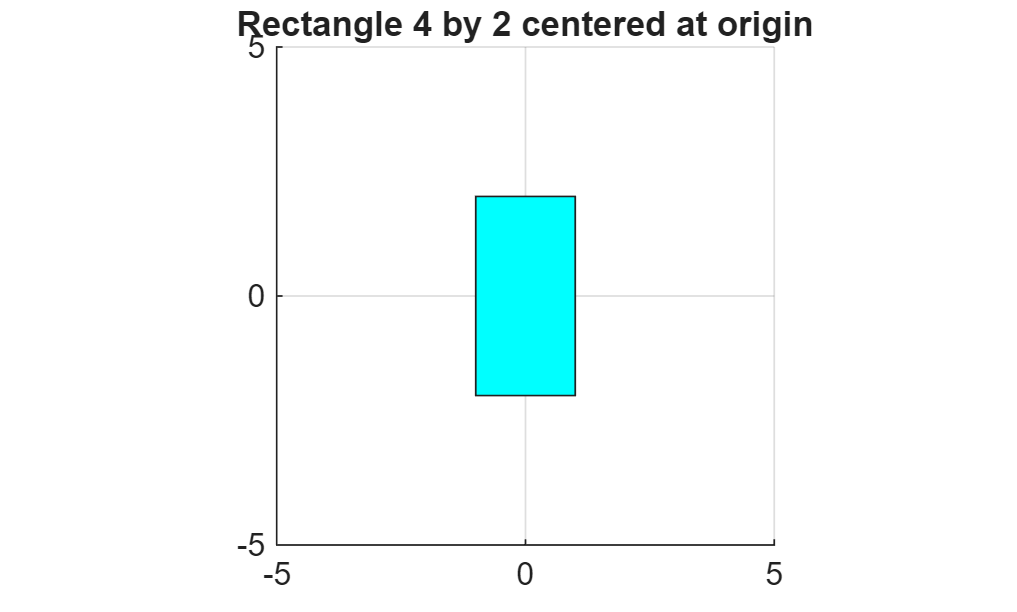

X = [-1 -1 1 1];
Y = [-2 2 2 -2];

f = figure('Name','Rectangle Transformation','NumberTitle','off');
hPatch = patch(X, Y, 'cyan'); 
axis equal; grid on;
xlim([-5.0 5.0]); ylim([-5.0 5.0]);
title('Rectangle 4 by 2 centered at origin');

##  Task 1: Rotation Only 

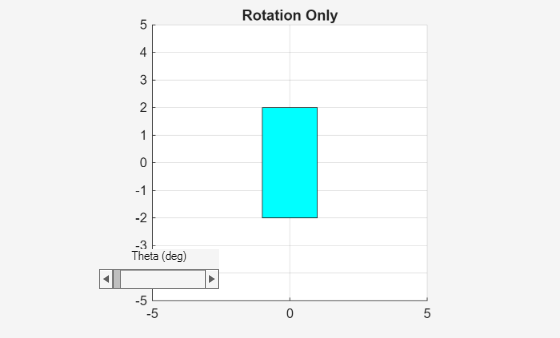


f1 = figure('Name','Task 1: Rotation','NumberTitle','off');
hPatch1 = patch(X, Y, 'cyan'); 
axis equal; grid on;
xlim([-5 5]); ylim([-5 5]);
title('Rotation Only');

thetaSlider1 = uicontrol('Style','slider','Min',0,'Max',360,'Value',0,...
    'Position',[100 50 120 20],'Callback',@updateRot);
uicontrol('Style','text','Position',[100 70 120 20],'String','Theta (deg)');


data1.X = X; data1.Y = Y; data1.hPatch = hPatch1; data1.thetaSlider = thetaSlider1;
guidata(f1,data1);

function updateRot(src,~)
    data = guidata(src);
    theta = deg2rad(get(data.thetaSlider,'Value'));
    Rz = [cos(theta) -sin(theta); sin(theta) cos(theta)];
    newCoords = Rz*[data.X; data.Y];
    set(data.hPatch,'XData',newCoords(1,:),'YData',newCoords(2,:));
end


## Task 2: Translation Only

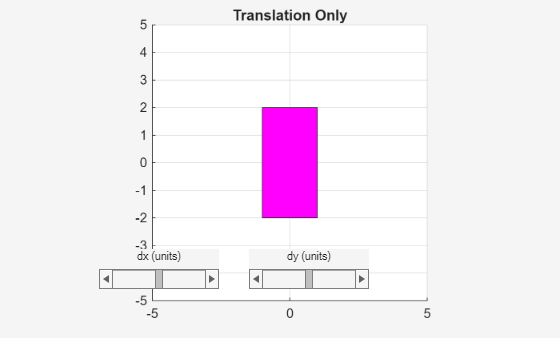


f2 = figure('Name','Task 2: Translation','NumberTitle','off');
hPatch2 = patch(X, Y, 'magenta'); 
axis equal; grid on;
xlim([-5 5]); ylim([-5 5]);
title('Translation Only');

dxSlider2 = uicontrol('Style','slider','Min',-4,'Max',4,'Value',0,...
    'Position',[100 50 120 20],'Callback',@updateTrans);
dySlider2 = uicontrol('Style','slider','Min',-4,'Max',4,'Value',0,...
    'Position',[250 50 120 20],'Callback',@updateTrans);
uicontrol('Style','text','Position',[100 70 120 20],'String','dx (units)');
uicontrol('Style','text','Position',[250 70 120 20],'String','dy (units)');


data2.X = X; data2.Y = Y; data2.hPatch = hPatch2; data2.dxSlider = dxSlider2; data2.dySlider = dySlider2;
guidata(f2,data2);

function updateTrans(src,~)
    data = guidata(src);
    dx = get(data.dxSlider,'Value');
    dy = get(data.dySlider,'Value');
    T = [1 0 dx; 0 1 dy; 0 0 1];
    newCoords = T*[data.X; data.Y; ones(1,length(data.X))];
    set(data.hPatch,'XData',newCoords(1,:),'YData',newCoords(2,:));
end


## Task 3: Transformation (Rotation + Translation)

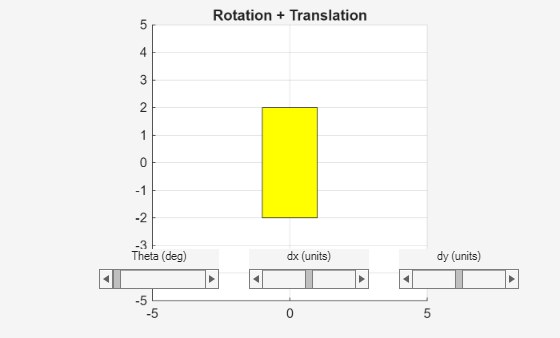


f3 = figure('Name','Task 3: Rotation + Translation','NumberTitle','off');
hPatch3 = patch(X, Y, 'yellow'); 
axis equal; grid on;
xlim([-5 5]); ylim([-5 5]);
title('Rotation + Translation');

thetaSlider3 = uicontrol('Style','slider','Min',0,'Max',360,'Value',0,...
    'Position',[100 50 120 20],'Callback',@updateTransform);
dxSlider3 = uicontrol('Style','slider','Min',-4,'Max',4,'Value',0,...
    'Position',[250 50 120 20],'Callback',@updateTransform);
dySlider3 = uicontrol('Style','slider','Min',-4,'Max',4,'Value',0,...
    'Position',[400 50 120 20],'Callback',@updateTransform);

uicontrol('Style','text','Position',[100 70 120 20],'String','Theta (deg)');
uicontrol('Style','text','Position',[250 70 120 20],'String','dx (units)');
uicontrol('Style','text','Position',[400 70 120 20],'String','dy (units)');


data3.X = X; data3.Y = Y; data3.hPatch = hPatch3;
data3.thetaSlider = thetaSlider3; data3.dxSlider = dxSlider3; data3.dySlider = dySlider3;
guidata(f3,data3);

function updateTransform(src,~)
    data = guidata(src);
    theta = deg2rad(get(data.thetaSlider,'Value')); % Angle in radians
    dx = get(data.dxSlider,'Value');
    dy = get(data.dySlider,'Value');
    T = [cos(theta) -sin(theta) dx;
         sin(theta)  cos(theta) dy;
         0           0          1];
    newCoords = T*[data.X; data.Y; ones(1,length(data.X))];
    set(data.hPatch,'XData',newCoords(1,:),'YData',newCoords(2,:));
end


## Use Matlab Built-in Rotation Matrices

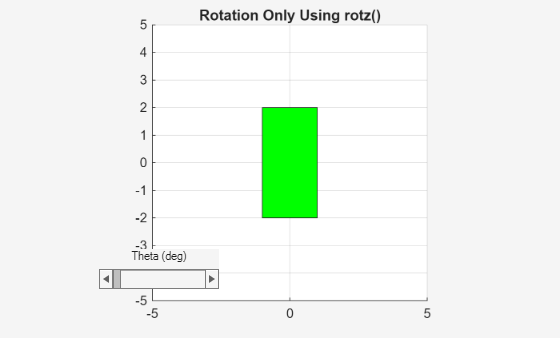

f1 = figure('Name','Task 1: Rotation Using rotz()','NumberTitle','off');
hPatch1 = patch(X, Y, 'green'); 
axis equal; grid on;
xlim([-5 5]); ylim([-5 5]);
title('Rotation Only Using rotz()');

thetaSlider1 = uicontrol('Style','slider','Min',0,'Max',360,'Value',0,...
    'Position',[100 50 120 20],'Callback',@updateRotz);
uicontrol('Style','text','Position',[100 70 120 20],'String','Theta (deg)');


data1.X = X; data1.Y = Y; data1.hPatch = hPatch1; data1.thetaSlider = thetaSlider1;
guidata(f1,data1);

function updateRotz(src,~)
    data = guidata(src);
    theta = get(data.thetaSlider,'Value'); % Angle in degrees
    R = rotz(theta);
    newCoords = R*[data.X; data.Y; ones(1, length(data.X))];
    set(data.hPatch,'XData',newCoords(1,:),'YData',newCoords(2,:));
end
